# Systematic review of SysID - correlation methods

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Jingxiao Liu
% Inferlab, CEE, CMU
% June, 2019
% This is my Matlab live script for introducing correlation methods
% Some contents are based on Arun K. Tangirala's SysID lecture in IIT
% and the textbook "System identification - an introduction" by Keesman
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Part 2. Prediction error methods --- 2-DoF mass-spring-damper system

Define stiffness and mass matrices

|\/\/\/\/\O\/\/\/\/\O

   k1 c1  m1  k2 c2  m2


$$M\ddot{X} +\textrm{C}\dot{X+} \textrm{KX}=F$$


clc;
clear;
close all;
addpath functions/
m1=5; %mass 1 [kg]
m2=2; %mass 2 [kg]
k1=200; %spring 1 [N/m]
k2=100; %spring 2 [N/m]
c1=10; % damping coeff 1
c2=10; % damping coeff 2
M=[m1 0;0 m2]; %mass matrix
K=[k1+k2 -k2; -k2 k2]; %stiffness matrix
Damp=[c1+c2 -c2; -c2 c2]; % damping matrix

## 2.1 Load the data generated in script 1

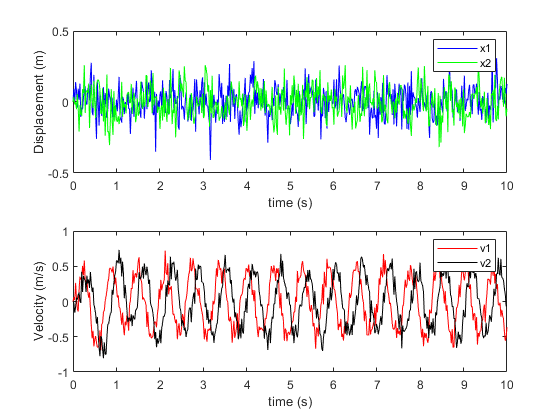

ysol = csvread(['data/2dof.csv']); %load data
T = 10; %length of time duration
nt = 500; %number of time stamps
tspan=linspace(0,T,nt);
figure(1)
plot_dv(tspan,ysol')

## 2.2 Autocorrelation function

The correlation of a signal with a delayed copy of itself as a function of delay.

It is a tool for finding repeating patterns.


$$\begin{array}{l}
r_{\mathit{uu}} \left(\tau ,t\right)=E\left\lbrack u\left(t\right)u\left(t+\tau \right)\right\rbrack =\lim_{T\to \infty } \frac{1}{2T}\int_{-T}^T u\left(t\right)u\left(t+\tau \right)\mathit{dt}\\
r_{\mathit{uu}} \left(l\right)=\lim_{T\to \infty } \frac{1}{2N+1}\sum_{i=-N}^N u\left(i\right)u\left(i+l\right)
\end{array}$$


where $\tau$ is the lag time.

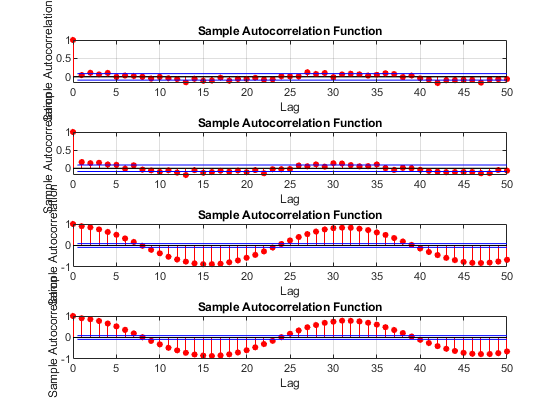

figure(2)
subplot(4,1,1)
autocorr(ysol(1,:),'NumLags',50)
subplot(4,1,2)
autocorr(ysol(2,:),'NumLags',50)
subplot(4,1,3)
autocorr(ysol(3,:),'NumLags',50)
subplot(4,1,4)
autocorr(ysol(4,:),'NumLags',50)

For a MA process, the autocorrelation fucntion abruptly vanishes after lages |l|>1;

For a AR process, the autocorrelation function decays exponentially.

## 2.3 Cross-correlation function


$$r_{\mathit{uy}} \left(\tau ,t\right)=E\left\lbrack u\left(t\right)y\left(t+\tau \right)\right\rbrack$$
